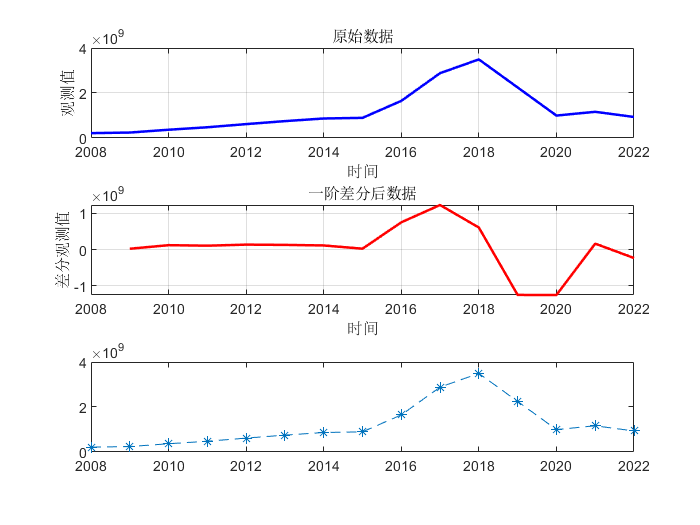

clear;clc
% 创建示例时间序列数据
rng(0); % 设置随机数种子以确保可重复性
data = [934858356.5 1164108036 997359077.9 2245986474 ...
3492602192 2882176947 1650071195 895180773.4 867045592.7 749945427.1 ...
617223209.6 477531317 367045995.4 242127461.7 216195957.6];
data = flip(data);
n = length(data); % 时间点数量
t = linspace(1,n,n); % 时间点索引


plot(linspace(2008,2022,15),data,'*',"LineStyle","--")

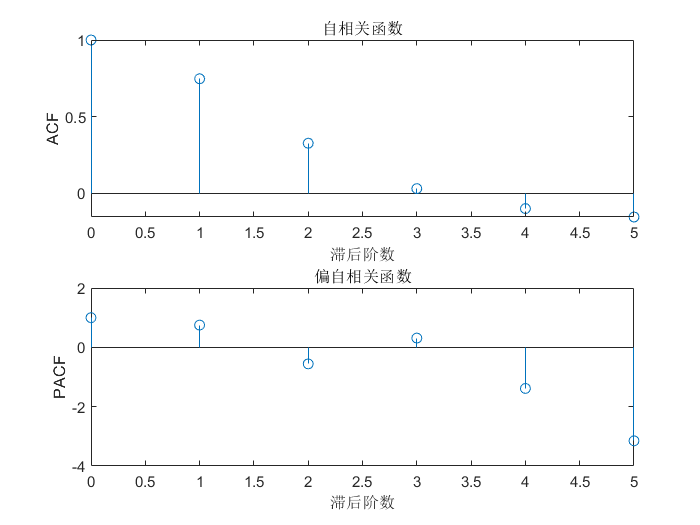

% 计算ACF和PACF
maxLag = 5; % 最大滞后阶数
[acf, lags] = autocorr(data', maxLag);
[pacf, lags_pacf] = parcorr(data, maxLag);

% 绘制ACF和PACF
figure;
subplot(2, 1, 1);
stem(lags, acf, 'Marker', "o");
xlabel('滞后阶数');
ylabel('ACF');
title('自相关函数');

subplot(2, 1, 2);
stem(lags_pacf, pacf, 'Marker', "o");
xlabel('滞后阶数');
ylabel('PACF');
title('偏自相关函数');

% 根据ACF和PACF确定P和Q值
% 选择P：观察PACF，在第一个显著截尾之后的滞后阶数可以作为P值
% 选择Q：观察ACF，在第一个显著截尾之后的滞后阶数可以作为Q值
% 注意：P和Q的选择可能不止一个，需要根据实际情况做出决策

% 拟合ARIMA模型
mdl = arima(2,2,0); % 创建ARIMA(2, 1, 1)模型
estMdl = estimate(mdl, data'); % 用时间序列数据y估计模型参数

 
    ARIMA(2,2,0) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue 
                ___________    _____________    ___________    ________

    Constant    -1.4479e+08     4.2819e-10      -3.3814e+17           0
    AR{1}           0.25748        0.25947          0.99231     0.32105
    AR{2}          -0.97603        0.41913          -2.3287    0.019876
    Variance     2.6485e+17     9.3776e-19       2.8243e+35           0



% Sim = simulate(mdl,10);
% 显示估计的模型参数
disp('Estimated ARIMA Parameters:');

Estimated ARIMA Parameters:


disp(estMdl.AR);

  列 1

    {[0.2575]}

  列 2

    {[-0.9760]}



disp(estMdl.D);

     2



disp(estMdl.MA);


% 获取模型的参数数量
numParams = numel(estMdl.AR) + numel(estMdl.MA) + 1; % AR参数数目 + MA参数数目 + 常数项

% 获取模型的拟合残差
residuals = infer(estMdl, data');

% 计算AIC和SBC值
n = length(data);
aicValue = n * log(var(residuals)) + 2 * numParams;
sbcValue = n * log(var(residuals)) + numParams * log(n);

disp(['AIC值：', num2str(aicValue)]);

AIC值：602.7228


disp(['SBC值：', num2str(sbcValue)]);

SBC值：604.8469


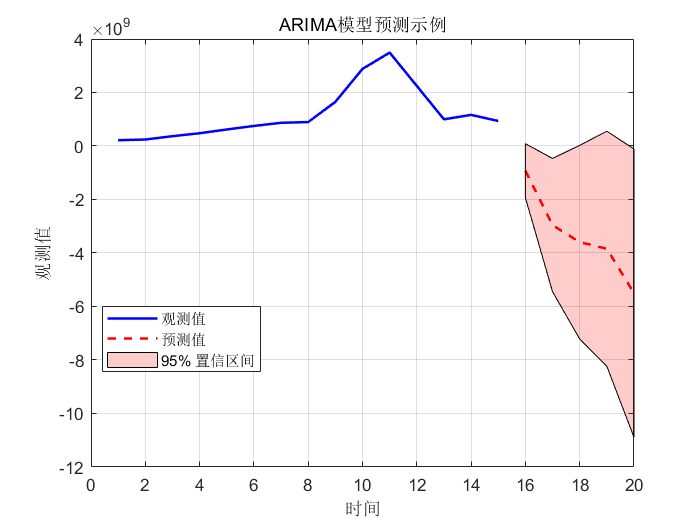

% 预测未来值
forecastHorizon = 5; % 预测未来10个时间点
[yF, yMSE] = forecast(estMdl, forecastHorizon, 'Y0', data'); % 预测未来值和均方误差

% 绘制结果
figure;
plot(t, data, 'b', 'LineWidth', 1.5);
hold on;
forecastIndex = t(end) + (1:forecastHorizon);
plot(forecastIndex, yF, 'r--', 'LineWidth', 1.5);
forecastUpper = yF + 1.96 * sqrt(yMSE); % 95% 置信上限
forecastLower = yF - 1.96 * sqrt(yMSE); % 95% 置信下限
fill([forecastIndex, fliplr(forecastIndex)], [forecastUpper', fliplr(forecastLower')], 'r', 'FaceAlpha', 0.2); % 绘制置信区间
title('ARIMA模型预测示例');
legend('观测值', '预测值', '95% 置信区间','Location','best');
xlabel('时间');
ylabel('观测值');
grid on;
hold off;

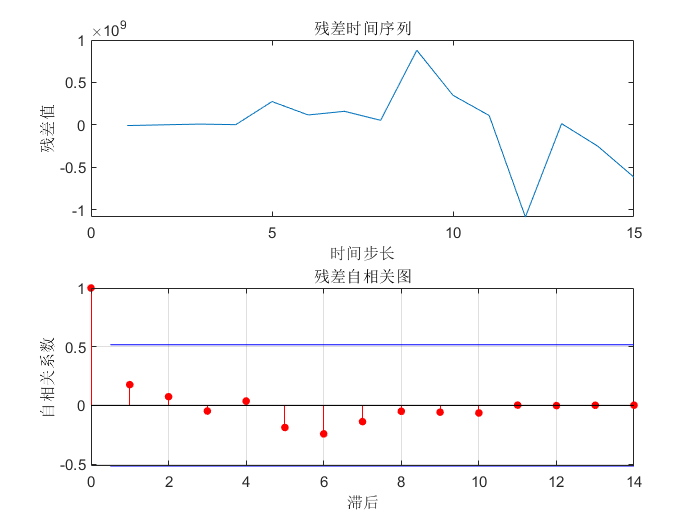

% 获取模型的残差
residuals = infer(estMdl, data');



% 绘制残差图
figure;
subplot(2, 1, 1);
plot(residuals);
title('残差时间序列');
xlabel('时间步长');
ylabel('残差值');

% 绘制残差自相关图（ACF）
subplot(2, 1, 2);
autocorr(residuals);
title('残差自相关图');
xlabel('滞后');
ylabel('自相关系数');

% 进行残差正态性检验
[h, pValue, ~, ~] = jbtest(residuals);
disp(['Jarque-Bera正态性检验结果：']);

Jarque-Bera正态性检验结果：


disp(['H0：残差服从正态分布']);

H0：残差服从正态分布


disp(['H1：残差不服从正态分布']);

H1：残差不服从正态分布


disp(['p值：', num2str(pValue)]);

p值：0.06115


if h == 0
    disp('根据p值，无法拒绝原假设，残差可能服从正态分布。');
else
    disp('根据p值，拒绝原假设，残差可能不服从正态分布。');
end

根据p值，无法拒绝原假设，残差可能服从正态分布。


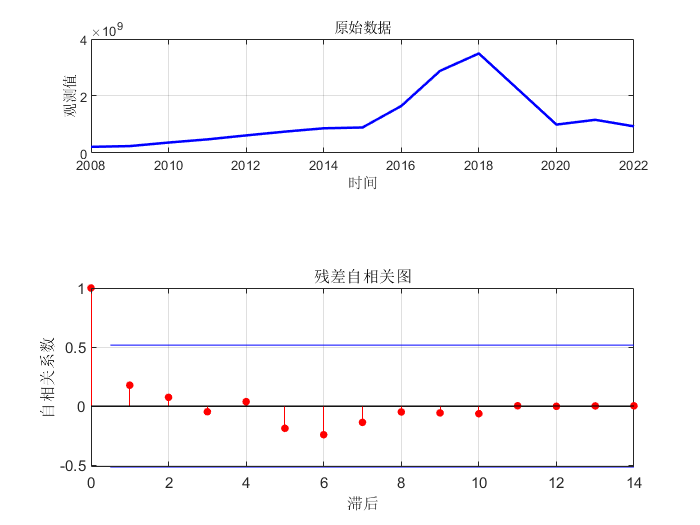

d = 1; % 差分阶数
diff_data = diff(data, d); % 进行1阶差分
diff_data_1 = diff(data, 2);
% 绘制原始数据和差分数据图像
t = linspace(2008,2022,15); % 时间点索引
t_diff = 2008 + [1:length(diff_data)]; % 差分数据的时间点索引
t_diff_1 = 2008 + [1:length(diff_data_1)];
subplot(3,1, 1);
plot(t, data, 'b', 'LineWidth', 1.5);
title('原始数据');
xlabel('时间');
ylabel('观测值');
grid on;

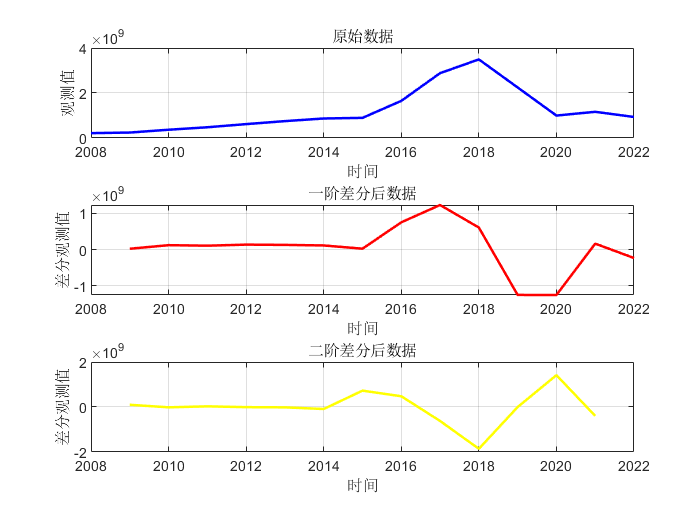


subplot(3,1, 2);
plot(t_diff, diff_data, 'r', 'LineWidth', 1.5);
title('一阶差分后数据');
xlabel('时间');
ylabel('差分观测值');
grid on;

subplot(3,1,3);
plot(t_diff_1, diff_data_1, 'y', 'LineWidth', 1.5);
title('二阶差分后数据');
xlabel('时间');
ylabel('差分观测值');
grid on;

% 进行ADF检验
[h, pValue, stat, cValue, reg] = adftest(diff_data_1);
disp(['ADF检验结果：']);

ADF检验结果：


disp(['H0：数据具有单位根，非平稳']);

H0：数据具有单位根，非平稳


disp(['H1：数据不具有单位根，平稳']);

H1：数据不具有单位根，平稳


disp(['p值：', num2str(pValue)]);

p值：0.0063623


if h == 0
    disp('根据p值，无法拒绝原假设，数据可能具有单位根，即非平稳。');
else
    disp('根据p值，拒绝原假设，数据可能不具有单位根，即平稳。');
end

根据p值，拒绝原假设，数据可能不具有单位根，即平稳。
